
% -----------------------------------
% Linear Fit for Spring Constant (k)
% -----------------------------------

% Preallocation and setup
num_measurements = 6; pos_means = zeros(1, num_measurements);
pos_std_deviations = zeros(1, num_measurements);
pos_err_mean = zeros(1, num_measurements); filename.Temp = "S4L6_%d.txt";

% Loop to import and process data
for i = 1:num_measurements
    data = readtable(sprintf(filename.Temp, i));
    current_positions = data.Position;
    N = length(current_positions);
    position_mean = mean(current_positions);
    pos_means(i) = position_mean;
    pos_std_deviations(i) = std(current_positions);
    pos_err_mean(i) = pos_std_deviations(i) / sqrt(N);
end

% Mass of weights in kg (from stamps on weights)
mass_weights = [0.0, 0.1, 0.2, 0.3, 0.4, 0.5];

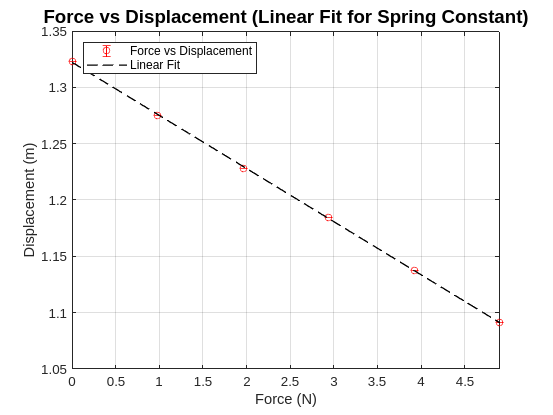

% Constants
g = 9.81; % Acceleration due to gravity (m/s^2)

% Convert Mass to Force
force_values = mass_weights * g;

% Perform Linear LSF between force and position according to Hooke's Law (F = k * x)
% Weights are calculated as 1 / (standard error mean)^2
[A, B, sigA, sigB] = linLSF_Derr(force_values, pos_means, 1 ./((pos_err_mean).^2));

% Calculate spring constant k from B (since B = 1/k) (do absolute value
% since the displacement should be inverted
k = abs(1 / B);
sigk = sigB / (B^2);

% Plot Linear Fit (Force vs Displacement)
figure; grid on; box on; hold on;

% Plot Original Data with Error Bars
errorbar(force_values, pos_means, pos_err_mean, 'ro', 'MarkerSize', 5, 'DisplayName', 'Force vs Displacement');

% Plot the Linear Fit
x_fit = linspace(min(force_values), max(force_values), 100);
y_fit = B * x_fit + A;
plot(x_fit, y_fit, 'k--', 'LineWidth', 1, 'DisplayName', 'Linear Fit');

% Labels and Legend
xlabel('Force (N)', 'FontSize', 11);
ylabel('Displacement (m)', 'FontSize', 11);
title('Force vs Displacement (Linear Fit for Spring Constant)', 'FontSize', 14);
legend('Location', 'northwest');

% Set x-axis limits to only plot the data within the range
xlim([min(force_values), max(force_values)]);

hold off;


% Print the Results
fprintf('Parameters and Uncertainties y = Bx + A:\n');

Parameters and Uncertainties y = Bx + A:


fprintf('-------------------------------------------\n');

-------------------------------------------


fprintf('Intercept (A) = %.4f ± %.4f m\n', A, sigA);

Intercept (A) = 1.3223 ± 0.0000 m


fprintf('Slope (B) = %.4f ± %.4f 1/N\n', B, sigB);

Slope (B) = -0.0472 ± 0.0000 1/N


fprintf('Spring constant (k) = %.2f ± %.2f N/m\n', k, sigk);

Spring constant (k) = 21.21 ± 0.00 N/m


fprintf('-------------------------------------------\n');

-------------------------------------------
